# **WM9QE: Applied Statistics for Artificial Intelligence**

**Lecturer: Dr. Ruohan Zhang**

## Analysis of Variance (ANOVA) in AI Applications 

This MATLAB Live Script is a suppliment to the ANOVA session. Full detail of the lectures and examples are availabe on the Week Moodle page.

Learning Objectives

- Explain the statistical foundations and assumptions underlying ANOVA.

- Differentiate between one-way and two-way ANOVA, interpret F-statistics and p-values.

- Evaluate model assumptions and apply suitable diagnostic tests.

- Implement ANOVA in MATLAB to analyse datasets and visualise results.

Overview

This tutorial provides hands-on experience with the descrite statistics techniques covered in the theoretical session. 

# Section 1: One-way ANOVA

This section compares three AI models (Logistic Regression, SVM, and Neural Network) to test whether their classification accuracies differ significantly.

Two approaches are demonstrated:

- **Method 1:** Manual calculation using statistical formulas

- **Method 2:** MATLAB built-in `anova1()` function

%% Reset environment
clear; clc;

% ==========================================================
% Simulated AI Model Accuracies (%)
% ==========================================================
LogReg = [81 83 84 85 82];   
SVM = [84 86 88 89 85];   
NN = [89 91 92 94 90];

% Combine into single vector and grouping labels
Accuracy = [LogReg SVM NN]';
Group = [repmat({'LogReg'},5,1);
         repmat({'SVM'},5,1);
         repmat({'NN'},5,1)];

% ==========================================================
% Summary statistics
% ==========================================================
means = [mean(LogReg), mean(SVM), mean(NN)];
overall_mean = mean(Accuracy);

fprintf('Model means: LogReg = %.2f, SVM = %.2f, NN = %.2f\n', means);

Model means: LogReg = 83.00, SVM = 86.40, NN = 91.20


fprintf('Overall mean = %.2f\n\n', overall_mean);

Overall mean = 86.87



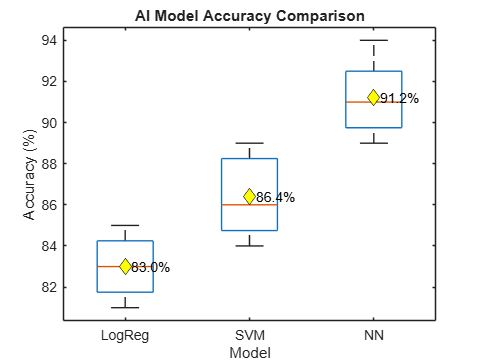

% ==========================================================
% Visualisation
% ==========================================================
% Create box plot
boxplot(Accuracy, Group);
title('AI Model Accuracy Comparison');
xlabel('Model');
ylabel('Accuracy (%)');

% Annotate mean values on plot
hold on;
model_positions = 1:3;
plot(model_positions, means, 'kd', 'MarkerFaceColor', 'y', 'MarkerSize', 8);
text(model_positions + 0.05, means, compose('%.1f%%', means), ...
    'Color', 'k', 'FontSize', 10);
hold off;

### Method 1: Manual One-Way ANOVA Calculation

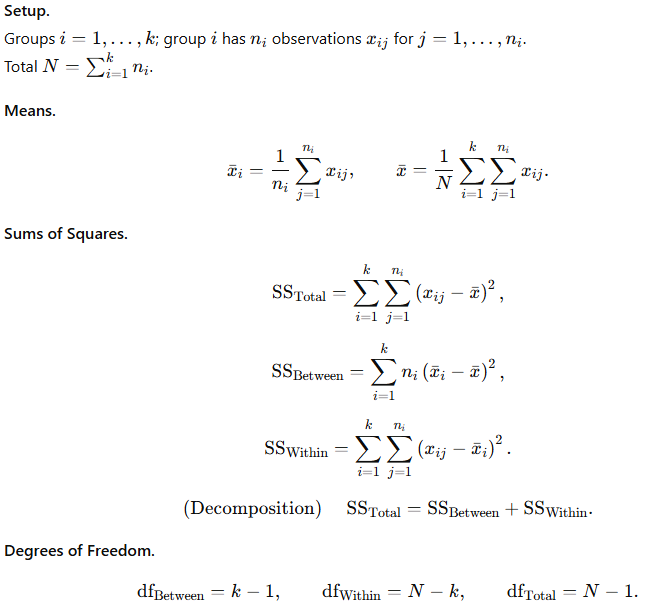

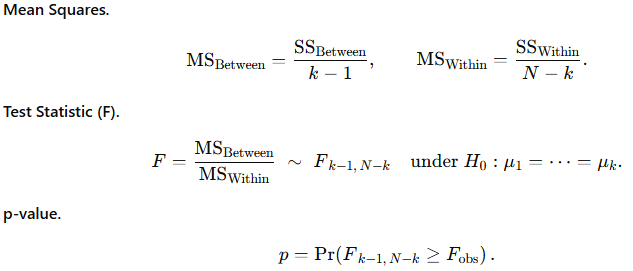

% ==========================================================
% Manual ANOVA (formula-based)
% ==========================================================

% Step 1: Between-group Sum of Squares
SS_between = 5 * sum((means - overall_mean).^2);

% Step 2: Within-group Sum of Squares
SS_within = sum((LogReg - means(1)).^2) + ...
             sum((SVM - means(2)).^2) + ...
             sum((NN - means(3)).^2);

% Step 3: Degrees of freedom
df_between = 3 - 1;  % k - 1
df_within = 15 - 3;  % N - k

% Step 4: Mean Squares
MS_between = SS_between / df_between;
MS_within = SS_within / df_within;

% Step 5: F-statistic
F_manual = MS_between / MS_within;

% Step 6: p-value
p_manual = 1 - fcdf(F_manual, df_between, df_within);

% Display manual ANOVA table
anovaManual = table(...
    [SS_between; SS_within], ...
    [df_between; df_within], ...
    [MS_between; MS_within], ...
    [F_manual; NaN], ...
    [p_manual; NaN], ...
    'VariableNames', {'SS','df','MS','F','pValue'}, ...
    'RowNames', {'Between Groups','Within Groups'});

disp('--- Manual One-way ANOVA Results ---');

--- Manual One-way ANOVA Results ---


anovaManual

anovaManual = 2×5 table
                        SS      df      MS        F        pValue  
                      ______    __    ______    ______    _________

    Between Groups    169.73     2    84.867    24.248    6.092e-05
    Within Groups         42    12       3.5       NaN          NaN


### Method 2: Using MATLAB Built-in Function

% ==========================================================
% MATLAB Built-in ANOVA Function
% ==========================================================
[p_func, tbl_func, stats_func] = anova1(Accuracy, Group, 'off');

% Convert ANOVA cell array to formatted table
anovaTable = cell2table(tbl_func(2:end,:), 'VariableNames', tbl_func(1,:));
disp('--- Built-in Function One-way ANOVA Results ---');

--- Built-in Function One-way ANOVA Results ---


anovaTable

anovaTable = 3×6 table
      来源        SS      df         MS              F             p 值(F)    
    ________    ______    __    ____________    ____________    ______________

    {'组'  }    169.73     2    {[ 84.8667]}    {[ 24.2476]}    {[6.0920e-05]}
    {'误差'}        42    12    {[  3.5000]}    {0×0 double}    {0×0 double  }
    {'合计'}    211.73    14    {0×0 double}    {0×0 double}    {0×0 double  }


### Result Comparison

% ==========================================================
% Compare Manual vs Built-in Results
% ==========================================================
fprintf('\n--- Comparison of Manual vs Function-based Results ---\n');


--- Comparison of Manual vs Function-based Results ---


fprintf('Manual: F = %.4f, p = %.6f\n', F_manual, p_manual);

Manual: F = 24.2476, p = 0.000061


fprintf('Function: F = %.4f, p = %.6f\n', anovaTable.F{1}, p_func);

Function: F = 24.2476, p = 0.000061



if p_manual < 0.05
    conclusion = "Significant difference detected between models (p < 0.05)";
else
    conclusion = "No significant difference between models (p ≥ 0.05)";
end
conclusion

conclusion = "Significant difference detected between models (p < 0.05)"

### Post-hoc Analysis

After finding a significant overall effect, post-hoc tests identify **which pairs of models** differ significantly. We can use MATLAB’s `multcompare()` function for Tukey’s *Honestly Significant Difference (HSD)* test.

% ==========================================================
% Post-hoc Multiple Comparisons (Tukey HSD)
% ==========================================================

% Run ANOVA
[p_func, tbl_func, stats_func] = anova1(Accuracy, Group, 'off');

% Get Tukey HSD results
[c, m, ~, gnames] = multcompare(stats_func, 'CType', 'tukey-kramer', 'Display', 'off');

% Convert to readable table
posthocTable = array2table(c, 'VariableNames', {'Group1_ID','Group2_ID','Lower_CI','Mean_Diff','Upper_CI','pValue'});

% Use correct variable names for ID mapping
posthocTable.Group1 = gnames(posthocTable.Group1_ID);
posthocTable.Group2 = gnames(posthocTable.Group2_ID);

% Reorder columns for clarity
posthocTable = movevars(posthocTable, {'Group1','Group2'}, 'Before', 'Lower_CI');

% Remove the numeric ID columns for cleaner display
posthocTable.Group1_ID = [];
posthocTable.Group2_ID = [];

% Inline formatted table output
posthocTable

posthocTable = 3×6 table
      Group1      Group2     Lower_CI    Mean_Diff    Upper_CI      pValue  
    __________    _______    ________    _________    ________    __________

    {'LogReg'}    {'SVM'}    -6.5567       -3.4       -0.24334      0.034743
    {'LogReg'}    {'NN' }    -11.357       -8.2        -5.0433    4.3627e-05
    {'SVM'   }    {'NN' }    -7.9567       -4.8        -1.6433     0.0041929


# Section 2: Two-way ANOVA

## Two-Way ANOVA (Without Replication)

Understand how to perform a **two-factor ANOVA when each cell has only one observation, **that is, when there are **no replicates per combination** of factors.

This test allows you to evaluate:

- The **main effect of each factor** (e.g., Model and Dataset), but

- It **cannot estimate interaction effects**, because no within-cell variability exists.

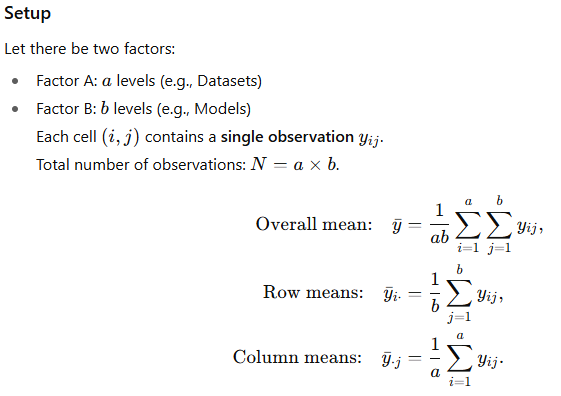

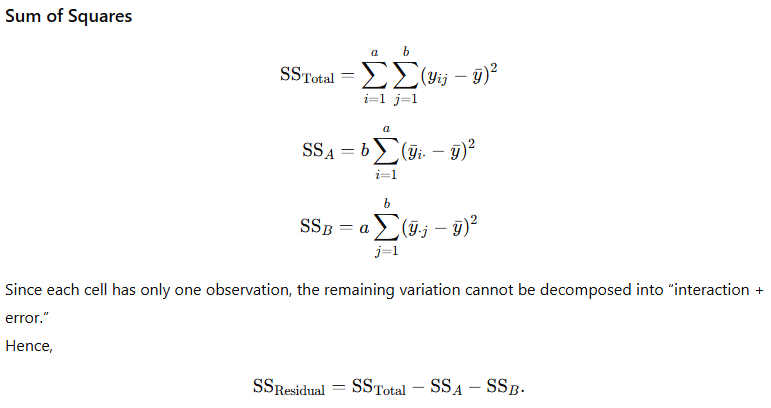

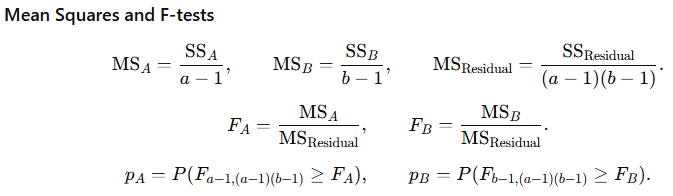

% ==========================================================
%  Two-Way ANOVA (Without Replication)
% ==========================================================
% Scenario:
% 3 AI models (columns) evaluated on 3 datasets (rows),
% each cell has only one accuracy measurement (%).
% This design tests main effects but not interactions.

Data = [88 93 95;     % Dataset 1 (e.g., MNIST)
        68 75 78;     % Dataset 2 (e.g., CIFAR-10)
        82 85 89];    % Dataset 3 (e.g., Fashion-MNIST)

% Perform two-way ANOVA without replication
[p_no, tbl_no] = anova2(Data, 1, 'off');  % '1' = one observation per cell

% Display ANOVA table
anovaTable_no = cell2table(tbl_no(2:end,:), 'VariableNames', tbl_no(1,:));
disp('--- Two-Way ANOVA (No Replication) Results ---');

--- Two-Way ANOVA (No Replication) Results ---


anovaTable_no

anovaTable_no = 4×6 table
      来源        SS      df         MS              F             p 值(F)    
    ________    ______    __    ____________    ____________    ______________

    {'列'  }        98    2     {[      49]}    {[ 36.7500]}    {[    0.0027]}
    {'行'  }    516.67    2     {[258.3333]}    {[193.7500]}    {[1.0439e-04]}
    {'误差'}    5.3333    4     {[  1.3333]}    {0×0 double}    {0×0 double  }
    {'合计'}       620    8     {0×0 double}    {0×0 double}    {0×0 double  }


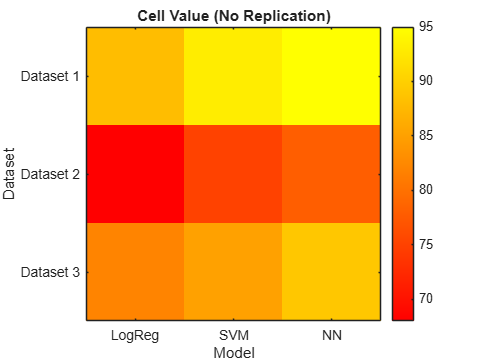


% Visualise mean pattern
figure
imagesc(Data); 
colorbar;
colormap("autumn")
xticks(1:3); 
xticklabels({'LogReg','SVM','NN'});
yticks(1:3); 
yticklabels({'Dataset 1','Dataset 2','Dataset 3'});
title('Cell Value (No Replication)');
xlabel('Model'); 
ylabel('Dataset');


% Interpret main effects
fprintf('\n[Two-Way ANOVA: No Replication]\n');


[Two-Way ANOVA: No Replication]


fprintf('Main effect p-values: Dataset = %.4f, Model = %.4f\n', p_no(1), p_no(2));

Main effect p-values: Dataset = 0.0027, Model = 0.0001



if p_no(1) < 0.05
    disp("Significant main effect of Dataset.");
else
    disp("No significant Dataset effect.");
end

Significant main effect of Dataset.



if p_no(2) < 0.05
    disp("Significant main effect of Model.");
else
    disp("No significant Model effect.");
end

Significant main effect of Model.



disp("Interaction cannot be tested (no replication).");

Interaction cannot be tested (no replication).


## Two-Way ANOVA (With Replication)

Perform a **two-factor ANOVA with replication**, where each factor combination has multiple observations (replicates).

This allows analysis of:

- **Main effects** of both factors

- **Interaction effect** between the two factors

- **Error term** estimated from within-cell variation

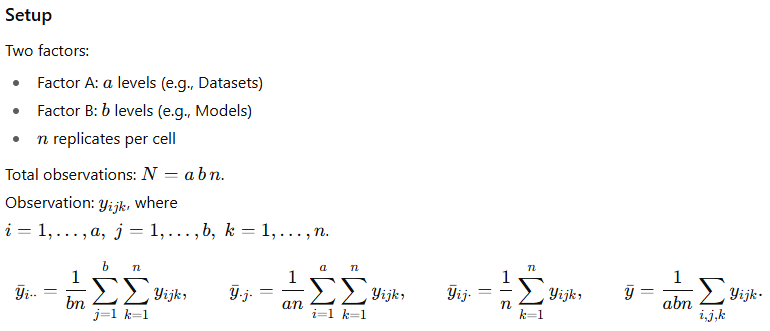

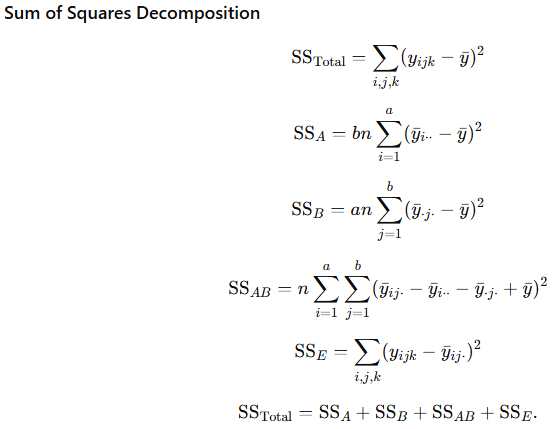

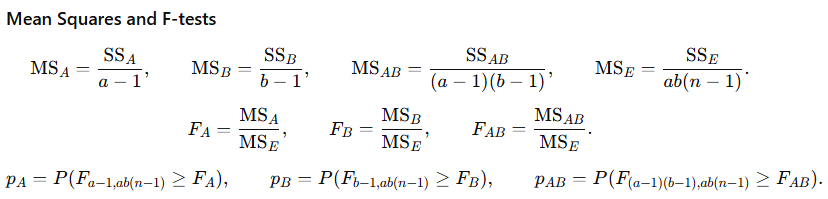

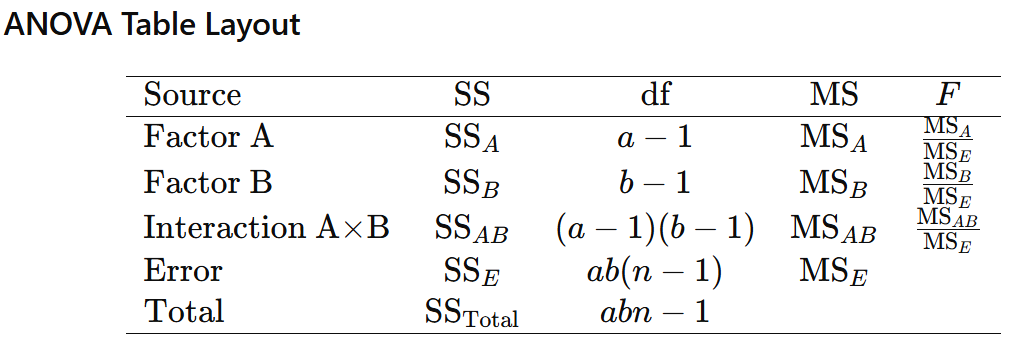

% Simulated accuracies (%) — 3×3×5 (Dataset × Model × Replicate)
DataR(:,:,1) = [86 91 93; 66 73 76; 80 83 87];
DataR(:,:,2) = [87 92 94; 67 74 77; 81 84 88];
DataR(:,:,3) = [88 93 95; 68 75 78; 82 85 89];
DataR(:,:,4) = [89 94 96; 69 76 79; 83 86 90];
DataR(:,:,5) = [90 95 97; 70 77 80; 84 87 91];

% Correct reshape for anova2 (replicates stacked in rows)
[a, b, n] = size(DataR);
DataR2D = reshape(permute(DataR, [3 2 1]), a*n, b);

% Perform two-way ANOVA with replication
[p_rep, tbl_rep, stats_rep] = anova2(DataR2D, n, 'off');

% Display formatted ANOVA table
anovaTable_rep = cell2table(tbl_rep(2:end,:), 'VariableNames', tbl_rep(1,:));
disp('--- Two-Way ANOVA (With Replication) Results ---');

--- Two-Way ANOVA (With Replication) Results ---


anovaTable_rep

anovaTable_rep = 5×6 table
       来源          SS      df          MS               F             p 值(F)    
    ___________    ______    __    ______________    ____________    ______________

    {'列'     }    2583.3     2    {[1.2917e+03]}    {[516.6667]}    {[3.0861e-27]}
    {'行'     }       490     2    {[       245]}    {[      98]}    {[2.7206e-15]}
    {'交互效应'}    26.667     4    {[    6.6667]}    {[  2.6667]}    {[    0.0479]}
    {'误差'   }        90    36    {[    2.5000]}    {0×0 double}    {0×0 double  }
    {'合计'   }      3190    44    {0×0 double  }    {0×0 double}    {0×0 double  }



% Extract and report p-values
p_dataset  = p_rep(1);
p_model    = p_rep(2);
p_interact = p_rep(3);

fprintf('\n[Two-Way ANOVA: With Replication]\n');


[Two-Way ANOVA: With Replication]


fprintf('Dataset p = %.4g | Model p = %.4g | Interaction p = %.4g\n', ...
    p_dataset, p_model, p_interact);

Dataset p = 3.086e-27 | Model p = 2.721e-15 | Interaction p = 0.04787



if p_dataset < 0.05
    disp("Significant main effect of Dataset.");  
else
    disp("No Dataset effect.");  
end

Significant main effect of Dataset.



if p_model < 0.05
    disp("Significant main effect of Model.");
else
    disp("No Model effect.");
end

Significant main effect of Model.



if p_interact < 0.05
    disp("Significant interaction detected (Dataset × Model).");
else
    disp("No significant interaction detected.");
end

Significant interaction detected (Dataset × Model).


## Concept Recap

# Interpretation of Results

## **1. Understanding ANOVA Output**

After running an ANOVA test (either one-way or two-way), MATLAB returns:

- **p-value:** Probability that the observed group differences occurred by chance.

- **F-statistic:** Ratio of variance *between groups* to variance **within groups** (larger F → stronger evidence against H₀).

- **df (Degrees of Freedom):** Reflects the number of independent comparisons available.

- **SS (Sum of Squares):** Quantifies total variability due to each source (factor, error, total).

- **MS (Mean Square):** Variance = SS / df, used to compute F.

## **2. Interpreting the p-value**

**Example:** If p = 0.018 when comparing model inference times, we conclude that at least one model has a different average runtime.

## **3. How to Interpret Main and Interaction Effects**

- **Main Effect (A):** Examines whether different levels of factor A lead to different outcomes. For example, Model Type (CNN vs Transformer vs LSTM).

- **Main Effect (B):** Examines factor B’s influence (e.g., Dataset or Optimizer).

- **Interaction (A×B):** Checks whether the effect of A depends on B. If significant (p < 0.05), it means the impact of one factor changes depending on the level of the other.

## **4. Post-hoc Analysis and Practical Conclusion**

When ANOVA shows significant differences, a **Post-hoc test (e.g., Tukey HSD)** is used to identify which specific groups differ.

- MATLAB’s `multcompare(stats)` command provides confidence intervals and pairwise comparisons.

- Always report both statistical and practical meaning (e.g., “Transformer is significantly slower than CNN but only by ~10 ms, which is acceptable for real-time applications”).

**5. Example Summary Template**

**Interpretation Example (One-Way ANOVA):**

The one-way ANOVA showed a significant effect of model type on inference time (F(2,12) = 8.43, p = 0.003).

Post-hoc Tukey tests revealed that the Transformer model was significantly slower than CNN and Vision-LSTM, while the latter two did not differ significantly.

# ANOVA Practice Exercises

## Exercise 1: Comparing Model Inference Times

**Scenario: **You tested three AI models (CNN, Transformer, and Vision-LSTM) on the same GPU for medical image inference.Each model was run **5 times**, and the average **inference time (ms)** was recorded. Please test if the **average inference time** differs among models.

% >>> Write your code here <<<


## Exercise 2: Dataset × Architecture

**Scenario: **You trained **three neural network architectures** (CNN, ResNet, Transformer) on **three medical datasets** (X-ray, MRI, CT). Each dataset–model pair has **one accuracy value** (no replication). Please test whether **model type** or **dataset type** affects accuracy.

% >>> Write your code here <<<
 

## Exercise 3: Optimizer × Model × Runs

**Scenario: **You evaluate **three optimizers** (SGD, Adam, RMSProp) across **three model architectures** (CNN, ResNet, Transformer). Each optimizer-model pair was tested **5 times**, and the **validation accuracy (%)** was recorded.

Please test:

- Main effect of Optimizer

- Main effect of Model

- Interaction between Optimizer × Model

% >>> Write your code here <<<
 